#           Antenna Array Processing

##                                            HW6

                 Mohammadreza Arani         :::::::::::::         810100511

                                                            1401/08/30        

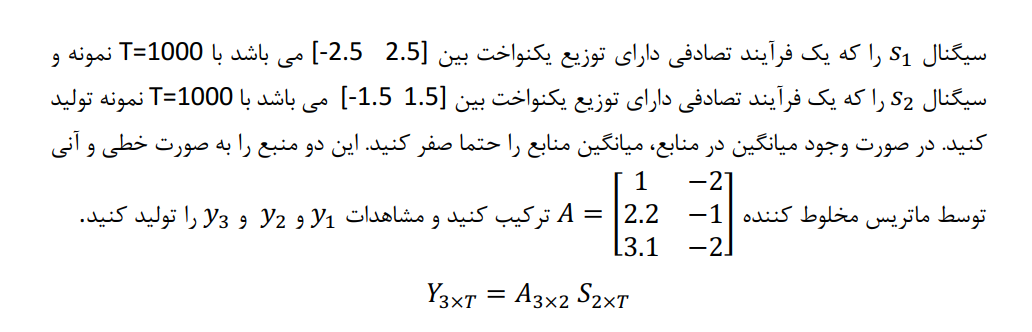

clear; clc; close all;

## Q1:

% Uniform Disttribution:
T = 1000;

a1 =-2.5*ones(1,T) ; b1 = 2.5*ones(1,T) ;
s1 = unifrnd(a1,b1);

a2 =-1.5*ones(1,T) ; b2 = 1.5*ones(1,T) ;
s2 = unifrnd(a2,b2);

% removing the bias from the distribution:
s1 = s1 - mean(s1);
s2 = s2 - mean(s2);

S = [s1 ; s2]; % 2*T

A = [1 -2; 2.2 -1; 3.1 -2]; % 3*2

Y = A*S ; % 3*T

## A:

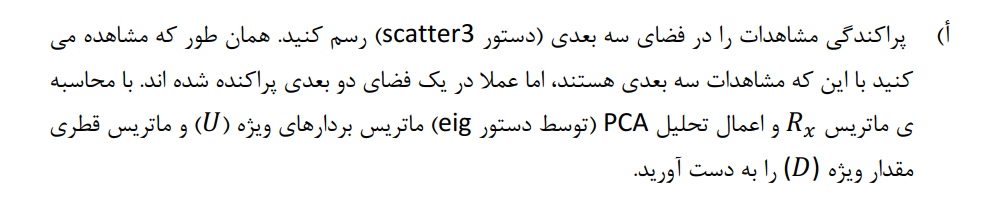

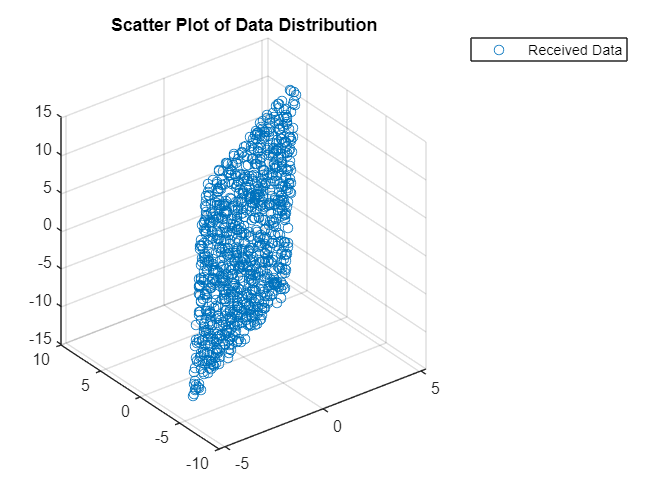

figure(1)
scatter3(Y(1,:) , Y(2,: ) , Y(3,:))% scatter3(X,Y,Z)
grid on
title("Scatter Plot of Data Distribution")
legend("Received Data")

It is obvious that received data is distributed mainly in a plane that is orthogonal to X,Y Axis and parallel (kind of) to Z axis where d/dz of this disribution is almost 0! --> meaning we can find a  plane where data has the most variance over that plane!

Rx = Y*Y' ; % YY^T
[U,Lambda] =  eig(Rx) ;

`[`[`V`](https://127.0.0.1:31515/static/help/matlab/ref/eig.html?searchHighlight=eig&searchResultIndex=1#btgapg5-1-V)`,`[`D`](https://127.0.0.1:31515/static/help/matlab/ref/eig.html?searchHighlight=eig&searchResultIndex=1#btgapg5-1-D)`] =` `eig``(`[`A`](https://127.0.0.1:31515/static/help/matlab/ref/eig.html?searchHighlight=eig&searchResultIndex=1#btgapg5-1-A)`)` returns diagonal matrix `D` of eigenvalues and matrix `V` whose columns are the corresponding right eigenvectors, so that `A*V = V*D`.

disp(size(U)) % Eigen-Vectors

     3     3



disp(size(Lambda)) % Eigen-Values

     3     3



disp("Trace of D: "+ trace(Lambda)+" and Trace of Rx: "+ trace(Rx)) % Trace of eigne-Values = Trace of Rx

Trace of D: 37485.1469 and Trace of Rx: 37485.1469


## B:

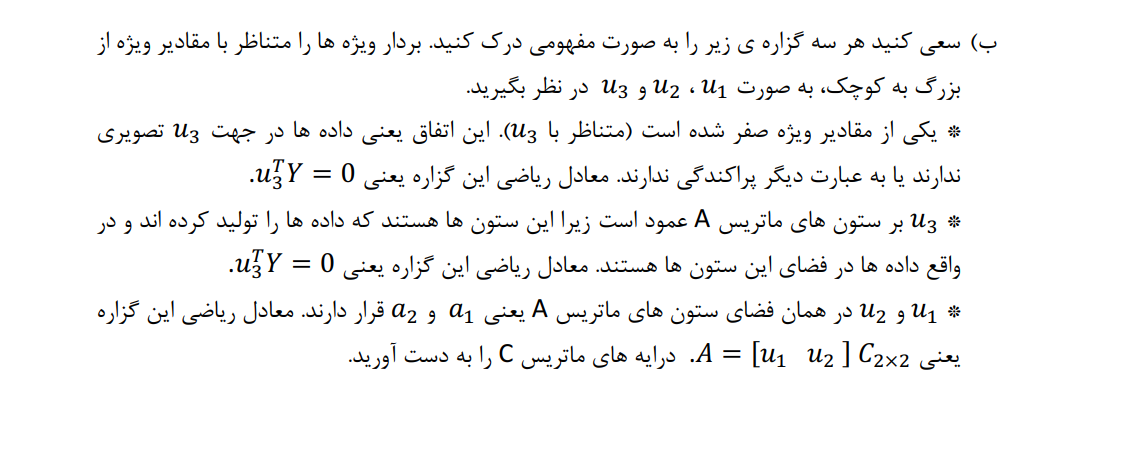

u3 = U(:,1);  Lambda_3 = Lambda(1,1);
u2 = U(:,2);  Lambda_2 = Lambda(2,2);
u1 = U(:,3);  Lambda_1 = Lambda(3,3);

disp(u1); % The best Vector to map Data to --> Based on Lambda values

    0.3269
    0.5314
    0.7815



disp(u2); % Second Best Vector

    0.9157
   -0.3828
   -0.1227



disp(u3); % The worst!

    0.2339
    0.7557
   -0.6117




disp(Lambda_3) % we can see that the value of this parameter is 0 --> No Variation in this direction (u3)

  -3.0757e-13



% It can be mentioned that u3 is orthogonal to data Space --> meaning
% describing a 2-D data with a 3-D coordinate system is possible but the
% rank of that system will be 2 and the nullity  of that system is 1 --> 
% Nullity + Rank  = Dimension --> 1 + 2 = 3  ! u1 and u2 are the 2
% orthogonal basis that best describe our data! --> Range of A can be
% described and spanned using u1 , u2
% 

To Obtain C: 

C = pinv([u1 , u2])*A;

## C:

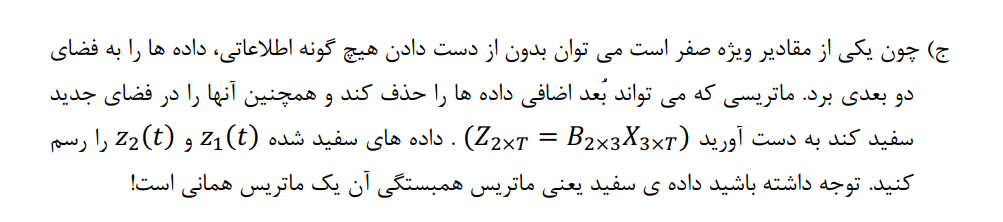

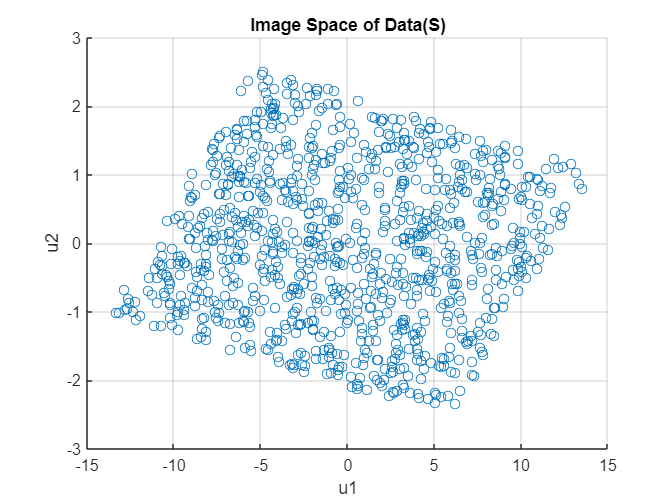

% Before we had:   Y = A*S % 3*T
% Now we will map these data to a new space -->
Z = [u1 , u2]'*Y ; % New Space --> Image SPace

figure(2)
scatter(Z(1,:) , Z(2,:));
grid on
xlabel("u1")
ylabel("u2")
title("Image Space of Data(S)")



Rz = Z*Z';
[U_z , Lambda_z]  = eig(Rz); 
% We can see the eigen vectors of the New Space:
disp(U_z)

     0     1
     1     0



% It is clear that we have 2 dimension and the U shall be rank-2 based on
% data dimension and 0 nullity --> It is satisfied! --> meaning we can span
% the data space using these 2 orthogonal vectors! Also means that the
% range of U matrix covers all the dimensions(2 dimensions)!
disp(Lambda_z)

   1.0e+04 *

    0.1250         0
         0    3.6235



% All eigen values are non zero! --> As expected

To whiten the data, we can assume a Whitening matrix, W to form:

Z_w  = W*Z --> Z_w * Z_w'  = W*Z*Z'*W'   ----------- >>>   for Z_w*Z_w' = I  we get to have a whitened Z_w where Rz_w = I !

-------- >>>>>   W * Rz * W'   = I = Rz_w  -------- >>>  W =  

  `[`[`U`](https://127.0.0.1:31515/static/help/matlab/ref/double.svd.html#bu2_0hq-U)`,`[`S`](https://127.0.0.1:31515/static/help/matlab/ref/double.svd.html#bu2_0hq-S)`,`[`V`](https://127.0.0.1:31515/static/help/matlab/ref/double.svd.html#bu2_0hq-V)`] = svd(`[`A`](https://127.0.0.1:31515/static/help/matlab/ref/double.svd.html#bu2_0hq-A)`)` performs a singular value decomposition of matrix `A`, such that `A = U*S*V'`.

Suppose  X   is a [random (column) vector](https://en.wikipedia.org/wiki/Random_vector) with non-singular covariance matrix  Σ   and mean  0  . 

Then the transformation Y= WX  with  a **whitening matrix** W satisfying the condition $W^T W=\Sigma^{-1} \;$                                 yields the whitened random vector Y with **unit diagonal covariance**.

There are infinitely many possible whitening matrices  W  that all satisfy the above condition.  

Commonly used choices are:

1)   W= Σ−1 / 2 (**Mahalanobis** or **ZCA** whitening), 

2) W=  $L^T$   where L is the [Cholesky decomposition](https://en.wikipedia.org/wiki/Cholesky_decomposition) of  $\Sigma^{-1}$ (Cholesky whitening), 

3) or the eigen-system of  Σ  (**PCA whitening**). 

[`R`](https://www.mathworks.com/help/matlab/ref/chol.html#mw_3e727a04-bd5b-42cd-b5bb-a3f7b411912e)` = chol(`[`A`](https://www.mathworks.com/help/matlab/ref/chol.html#mw_91dc7b0f-768f-4a6b-ab21-391fd8ee5851)`)` factorizes symmetric positive definite matrix `A` into an upper triangular `R` that satisfies `A = R'*R`. If `A`        is nonsymmetric , then `chol` treats the matrix as symmetric and uses only the diagonal and upper triangle of `A`.

% whiten the Z data:
W = chol(inv(Rz));


Z_w = W*Z ;
Rz_w = Z_w*Z_w';

disp(Rz_w) % It is obvious that we are dealing with I matrix! 

    1.0000    0.0000
    0.0000    1.0000



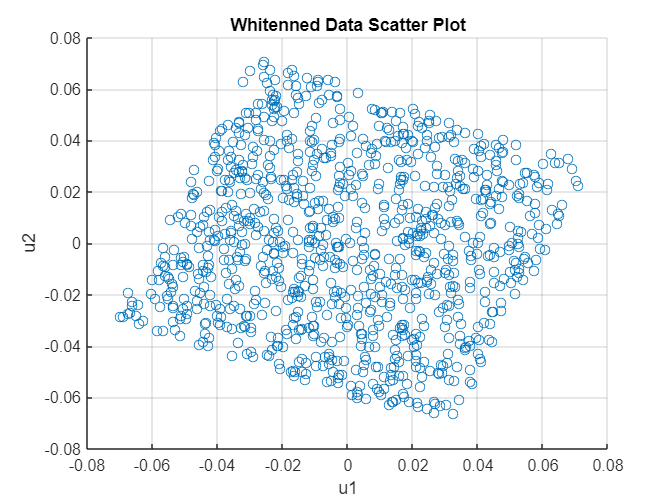


figure(3)
scatter(Z_w(1,:),Z_w(2,:))
grid on
title("Whitenned Data Scatter Plot")
xlabel("u1");
ylabel("u2")

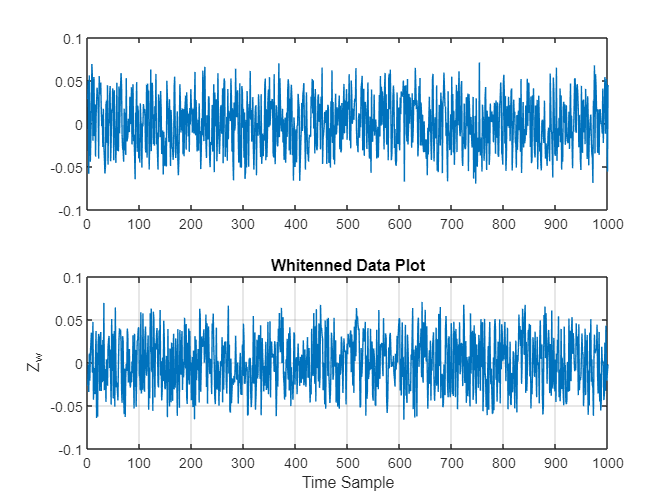

figure(4)
subplot(2,1,1)
plot(Z_w(1,:))
subplot(2,1,2)
plot(Z_w(2,:))
grid on
title("Whitenned Data Plot")
xlabel("Time Sample");
ylabel("Z_w")

## D:

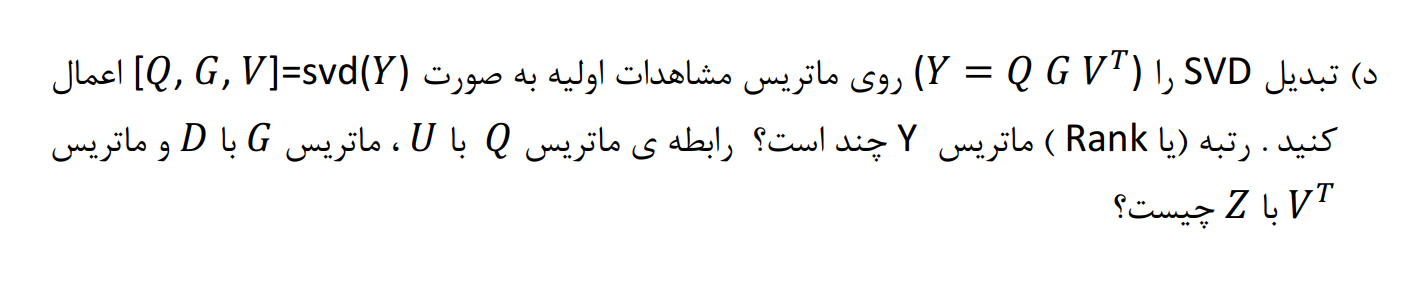

[Q,G,V] = svd(Y)

Q =    -0.3269   -0.9157   -0.2339
   -0.5314    0.3828   -0.7557
   -0.7815    0.1227    0.6117


G =   190.3557         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   35.3533         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

V =    -0.0283    0.0265    0.0589   -0.0546    0.0022    0.0357    0.0041   -0.0360   -0.0746   -0.0411   -0.0051   -0.0149   -0.0450    0.0290   -0.0024    0.0295   -0.0242    0.0087   -0.0423    0.0028   -0.0366    0.0196   -0.0617   -0.0200   -0.0417   -0.0589    0.0004   -0.0073    0.0013    0.0114   -0.0051   -0.0101    0.0495    0.0567    0.0479    0.0027   -0.0253    0.0213   -0.0266    0.0337   -0.0168   -0.0152   -0.0246   -0.0462    0.0463    0.0413   -0.0385   -0.0088   -0.0520    0.0066
   -0.0496    0.0023   -0.8904   -0.0144   -0.0102    0.0111    0.0046   -0.0012    0.0198   -0.0100   -0.0013    0.0035   -0.0166    0.0011   -0.0063   -0.0011    0.0038   -0.0222    0.0128   -0.0217   -0.0107   -0.0212    0.0135   -0.0120    0.0108    0.0198   -0.0256    0.0078   -0.0148    0.0122   -0.0125    0.0283   -0.0081    0.0626    0.0025   -0.0143    0.0086    0.0010   -0.0052    0.0187    0.0090   -0.0026   -0.0199   -0.0305   -0.0296    0.0070    0.0063   -0.0027    0.0108   -0

disp(U)

    0.2339    0.9157    0.3269
    0.7557   -0.3828    0.5314
   -0.6117   -0.1227    0.7815



Singular value decomposition

`[`[`U`](https://www.mathworks.com/help/releases/R2022a/matlab/ref/double.svd.html?searchHighlight=svd&s_tid=doc_srchtitle#bu2_0hq-U)`,`[`S`](https://www.mathworks.com/help/releases/R2022a/matlab/ref/double.svd.html?searchHighlight=svd&s_tid=doc_srchtitle#bu2_0hq-S)`,`[`V`](https://www.mathworks.com/help/releases/R2022a/matlab/ref/double.svd.html?searchHighlight=svd&s_tid=doc_srchtitle#bu2_0hq-V)`] =` `svd``(`[`A`](https://www.mathworks.com/help/releases/R2022a/matlab/ref/double.svd.html?searchHighlight=svd&s_tid=doc_srchtitle#bu2_0hq-A)`)` performs a singular value decomposition of matrix `A`, such that `A = U*S*V'`.

S matrix is the singular value matrix corresponding to Eigen vectors of matrix U for given matrix A. --- >>> SST gives the eigen values of Matrix A.

Also, S corresponding values determines the variation of data over eigenvectors in U.

It is Obvious that Q is exactly the same as U but the order of columns and their sign have been chnaged!

disp(abs(sqrt(Lambda)))

    0.0000         0         0
         0   35.3533         0
         0         0  190.3557



disp(G(:,1:3))

  190.3557         0         0
         0   35.3533         0
         0         0    0.0000



% We can see G(:,1:3) = abs(sqrt(Lambda)) -- >> eigen values of Ry
% Other columns of G are all 0!

disp(G(find(G>1e-10))) % Non-zero elements of diagnal Matrix G:

  190.3557
   35.3533



% Number of nonzero columns of G is 2 as can be observed!
rank_Y = rank(Y); % Non-zero Columns of diagnal Matrix G_d --> actually here, G_d is equal to G
% G is a diagnal matrix of singular values in descending form!
disp("Rank of Y is: "+rank_Y)

Rank of Y is: 2


This means Y is not Full-rank Matrix --> rank_Y + Nullity_Y = Dimension -- >>> 2 + 1 =3;

Z is described using first 2 rows of V:

% 2 First Rows of V' show Z
Check = Z*V;
disp(sum(sum(abs(Check)>1e-10)));

     2



     0



## E:

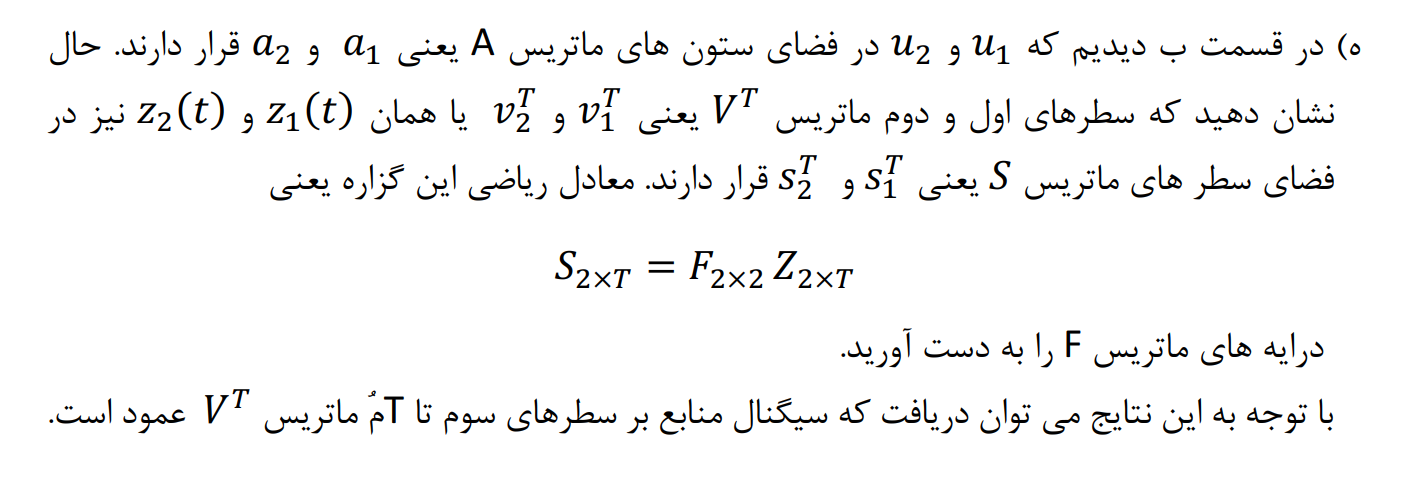

% With respect to above relationship between S,F and Z:
F_z = S*pinv(Z);
F_z_w =  S*pinv(Z_w);
Temp =(S*V)';
disp(Temp(1:10,:)) % S is orthogonal to all rows of V but the first two of them!

  -41.2075   10.5079
   17.4809   24.9264
    0.0000    0.0000
    0.0000    0.0000
    0.0000   -0.0000
   -0.0000   -0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
   -0.0000    0.0000



## F:

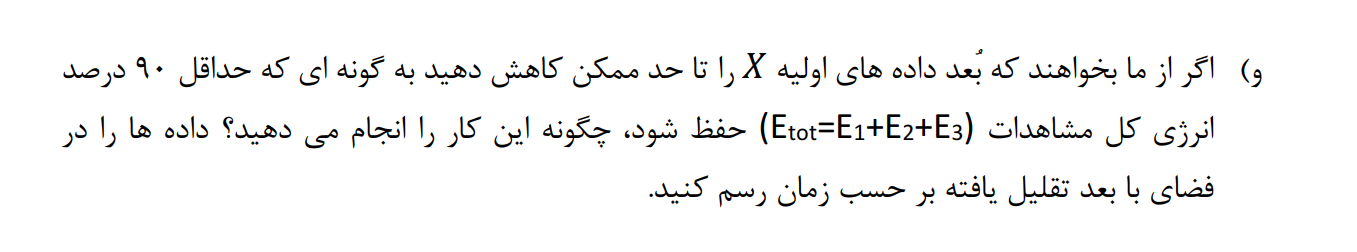


% Total Energy of Received Signal:
Etot = trace(Lambda);

Proportional_E = [Lambda_1 , Lambda_2, Lambda_3 ] / Etot;
disp(Proportional_E); % with respect to Energy Values -- >> to contain at least 90% of energies 

    0.9667    0.0333   -0.0000



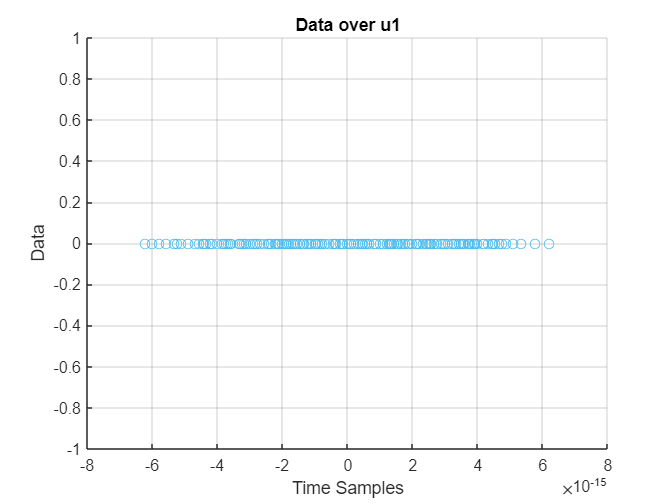

% in received Signal
% It is wise to Map Data over u1 solely! == >>> This preserves 96% of the
% Energy , More than desired 90%
Y_PCA = U(:,1)'*Y; % Mapping Over u1
figure(5)
scatter(Y_PCA(1,:), zeros(length(Y_PCA)))
grid on
title("Data over u1")
xlabel("Time Samples")
ylabel("Data")